### Generate some data

% Generate data with 2x2 design and a grouping variable
cities = ["Lexington", "Louisville"];
cuisines = ["Italian", "French", "Scottish"];
reviewers = ["Fiona", "Tucker", "Maggie", "Patterson"];

mean_scores = [1, 1.1, 1.05 ; 1.4, 1.5, 1.55];
noise = 0.2;
reviewer_effect = 0.1;

% Reset random generator for repeatility
rng(1);

% Loop through the table
counter = 0;
for i = 1 : numel(cities)
    for j = 1 : numel(cuisines)

        % Set a random number of scores
        n = 5 + randi(10, 1);
        vi = counter + (1:n);
        y(vi) = mean_scores(i,j) + (noise * (randn([n, 1]) - 0.5));
        city(vi) = repmat(cities(i), [n, 1]);
        cuisine(vi) = repmat(cuisines(j), [n, 1]);
        reviewer_ind = randi(numel(reviewers), [n, 1]);
        reviewer(vi) = reviewers(reviewer_ind);
        y(vi) = y(vi) + reviewer_effect * reviewer_ind';

        % Update counter for the next loop
        counter = counter + n;
    end
end

t = table(y', city', cuisine', reviewer', ...
        VariableNames = ["Score", "City", "Cuisine", "Reviewer"])

t = 65×4 table
     Score        City         Cuisine      Reviewer  
    _______    ___________    _________    ___________
     1.5362    "Lexington"    "Italian"    "Patterson"
    0.84831    "Lexington"    "Italian"    "Fiona"    
    0.97808    "Lexington"    "Italian"    "Maggie"   
    0.93089    "Lexington"    "Italian"    "Tucker"   
     1.0855    "Lexington"    "Italian"    "Maggie"   
    0.88826    "Lexington"    "Italian"    "Fiona"    
     1.0357    "Lexington"    "Italian"    "Fiona"    
     1.2606    "Lexington"    "Italian"    "Patterson"
     1.4173    "Lexington"    "Italian"    "Patterson"
    0.92962    "Lexington"    "Italian"    "Tucker"   
     1.6563    "Lexington"    "French"     "Maggie"   
     1.7547    "Lexington"    "French"     "Patterson"
    0.72698    "Lexington"    "French"     "Fiona"    
     1.1898    "Lexingto

### Create a one-factor figure

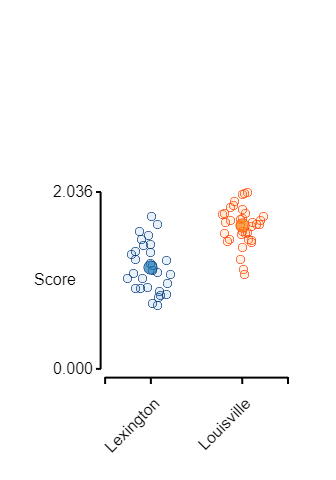

fig_jitter(t, "Score", "City");

### Create a one-factor figure but no means

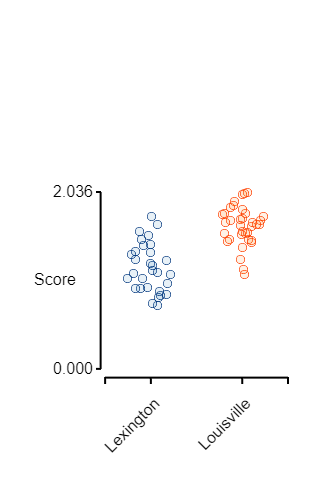

fig_jitter(t, "Score", "City", ...
    super_plot = false);

### Create a one-factor figure with grouping

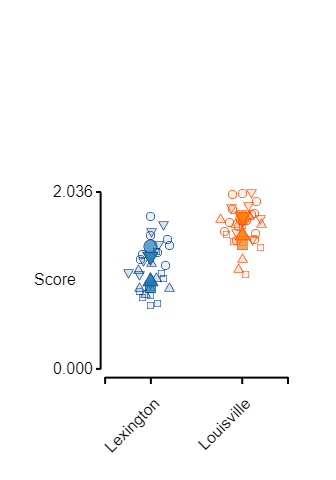

fig_jitter(t, "Score", "City", ...
    grouping_label = "Reviewer")

### Create a one-factor figure with grouping and linkages shown

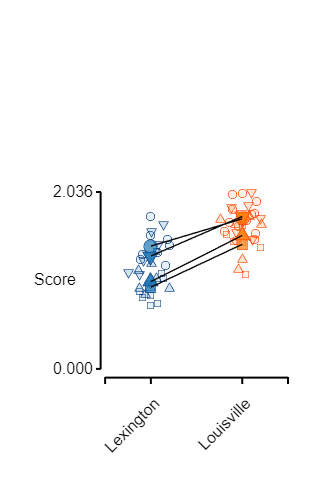

fig_jitter(t, "Score", "City", ...
    grouping_label = "Reviewer", ...
    join_points = true)

### Create a two-factor figure

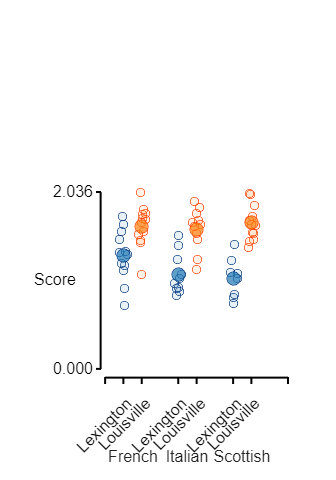

fig_jitter(t, "Score", "City", ...
    f2_label = "Cuisine")

### Adjust the figure size

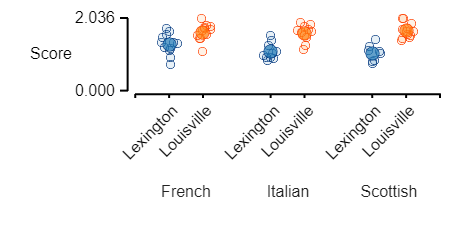

% Need to tweak the padding as well as the width to make sure
% labels fit
sub_plot = layout_subplots(figure_width = 5, ...
    x_to_y_ratio = 4, ...
    padding_left = 1.3, ...
    padding_bottom = 1.5);

% And here, need to adjust the y position of the f2 labels
fig_jitter(t, "Score", "City", ...
    f2_label = "Cuisine", ...
    subplot_handle = sub_plot, ...
    f2_label_rel_pos = -1.4)

### Calculate and show statistical results for one-way table

stats = linear_mixed_model(t, "Score", "City");

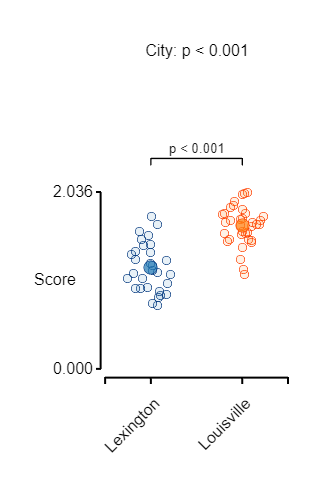


fig_jitter(t, "Score", "City", ...
    title_string = stats.main_effects_string, ...
    post_hoc_table = stats.post_hoc)

### Calculate and show statistical results for one-way table with grouping

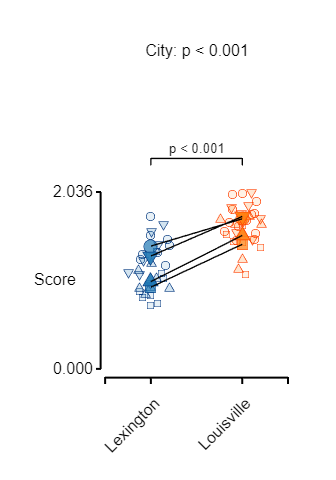

stats = linear_mixed_model(t, "Score", "City", ...
    grouping_label = "Reviewer");

fig_jitter(t, "Score", "City", ...
    grouping_label = "Reviewer", ...
    title_string = stats.main_effects_string, ...
    post_hoc_table = stats.post_hoc, ...
    join_points = true)

### Calculate and show statistical results for two-way table

stats = linear_mixed_model(t, "Score", "City", ...
    f2_label = "Cuisine");

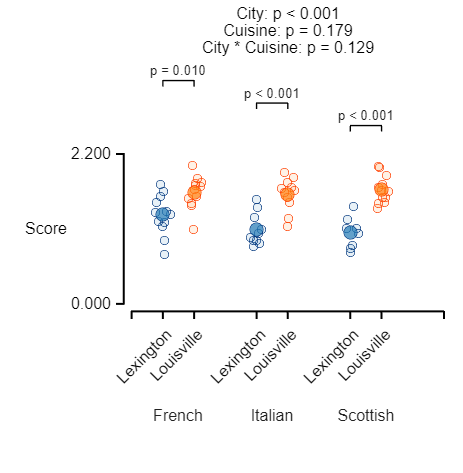


% Need to make the layout with big enough padding to
% show labels and results
sub_plot = layout_subplots(figure_width = 6, ...
    x_to_y_ratio = 2, ...
    padding_top = 2, ...
    padding_bottom = 2, ...
    padding_left = 1.5);

fig_jitter(t, "Score", "City", ...
    f2_label = "Cuisine", ...
    subplot_handle = sub_plot, ...
    title_string = stats.main_effects_string, ...
    post_hoc_table = stats.post_hoc, ...
    f2_label_rel_pos = -0.75)

### Calculate and show statistical results for two-way table with grouping

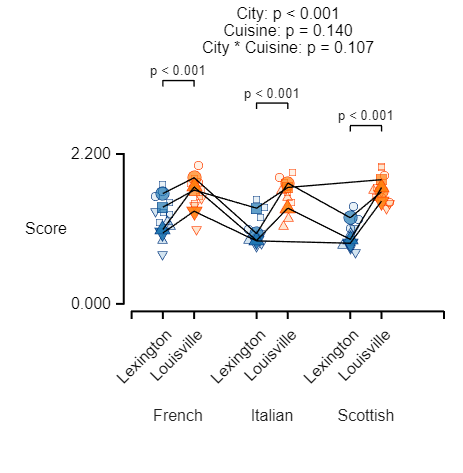

stats = linear_mixed_model(t, "Score", "City", ...
    f2_label = "Cuisine", ...
    grouping_label = "Reviewer");

% Need to make the layout with big enough padding to
% show labels and results
sub_plot = layout_subplots(figure_width = 6, ...
    x_to_y_ratio = 2, ...
    padding_top = 2, ...
    padding_bottom = 2, ...
    padding_left = 1.5);

fig_jitter(t, "Score", "City", ...
    f2_label = "Cuisine", ...
    grouping_label = "Reviewer", ...
    subplot_handle = sub_plot, ...
    title_string = stats.main_effects_string, ...
    post_hoc_table = stats.post_hoc, ...
    join_points = true, ...
    f2_label_rel_pos = -0.75)